# Figure 4: S_EE and S_II

clear

## 1. Select background parameters

CurrentFolder = pwd

CurrentFolder = 'C:\Users\tiexu\OneDrive\文档\Researches\NYU-Vision\MFModel Code'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
addpath([CurrentFolder '/HPCData'])

S_EEtest = [0.018 0.021 0.024 0.027 0.030]; 
S_IItest = [0.08  0.12  0.16  0.20];
Panel1 = length(S_EEtest); Panel2 = length(S_IItest);
S_ElgnInd = 3;
S_IlgnInd = 2; % $(seq 2 4)
rI_L6Ind = 3;  % 3 6

## 4. Good Areas

white frE = [3 5], frI/frE = (3, 4.25)

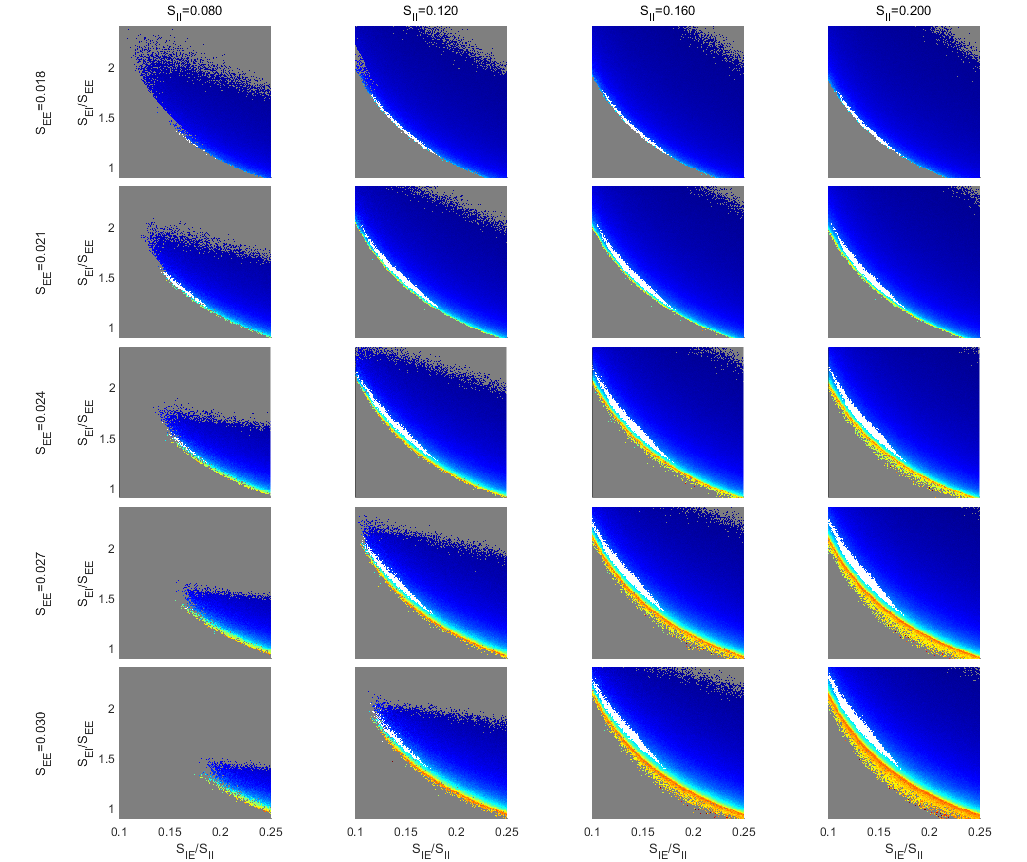

ans = 'id1 = 0.02, id2 = 0.08, Fail = 0.41, SIEWgt = 1.26'

ans = 'id1 = 0.02, id2 = 0.12, Fail = 0.68, SIEWgt = 1.10'

ans = 'id1 = 0.02, id2 = 0.16, Fail = 0.75, SIEWgt = 1.10'

ans = 'id1 = 0.02, id2 = 0.20, Fail = 0.78, SIEWgt = 1.10'

ans = 'id1 = 0.02, id2 = 0.08, Fail = 0.32, SIEWgt = 1.31'

ans = 'id1 = 0.02, id2 = 0.12, Fail = 0.65, SIEWgt = 1.10'

ans = 'id1 = 0.02, id2 = 0.16, Fail = 0.74, SIEWgt = 1.13'

ans = 'id1 = 0.02, id2 = 0.20, Fail = 0.77, SIEWgt = 1.14'

ans = 'id1 = 0.02, id2 = 0.08, Fail = 0.23, SIEWgt = 1.41'

ans = 'id1 = 0.02, id2 = 0.12, Fail = 0.59, SIEWgt = 1.13'

ans = 'id1 = 0.02, id2 = 0.16, Fail = 0.73, SIEWgt = 1.14'

ans = 'id1 = 0.02, id2 = 0.20, Fail = 0.77, SIEWgt = 1.15'

ans = 'id1 = 0.03, id2 = 0.08, Fail = 0.15, SIEWgt = 1.53'

ans = 'id1 = 0.03, id2 = 0.12, Fail = 0.49, SIEWgt = 1.20'

ans = 'id1 = 0.03, id2 = 0.16, Fail = 0.72, SIEWgt = 1.15'

ans = 'id1 = 0.03, id2 = 0.20, Fail = 0.77, SIEWgt = 1.15'

ans = 'id1 = 0.03, id2 = 0.08, Fail = 0.08, SIEWgt = 1.66'

ans = 'id1 = 0.03, id2 = 0.12, Fail = 0.39, SIEWgt = 1.28'

ans = 'id1 = 0.03, id2 = 0.16, Fail = 0.69, SIEWgt = 1.14'

ans = 'id1 = 0.03, id2 = 0.20, Fail = 0.77, SIEWgt = 1.15'

Fig1 = figure('Name','SEE_SII','units','normalized','outerposition',[0 0 0.67 1]);

ha = tight_subplot(Panel1,Panel2,[.01 .01],[.05 .03],[.08 .01]);

for S_EEInd = 1:length(S_EEtest)
    S_EE = S_EEtest(S_EEInd);
    S_Elgntest = [1.5 2 2.5 3.0]*S_EE;
    S_Elgn=S_Elgntest(S_ElgnInd);
    for S_IIInd = 1:length(S_IItest)
        S_II = S_IItest(S_IIInd);
        S_Ilgntest = [1.5 2 2.5 3]*S_Elgn;
        S_Ilgn = S_Ilgntest(S_IlgnInd);
        
        CurrentPanelFile = sprintf('FigContourL_S_EE=%.3f_S_II=%.2f_S_ElgnInd=%d_S_IlgnInd%d_rI_L6Ind%d.mat',...
                                               S_EE,     S_II,     S_ElgnInd,   S_IlgnInd,  rI_L6Ind);
        if isfile([CurrentFolder '/HPCData/' CurrentPanelFile])
        load(sprintf('FigContourL_S_EE=%.3f_S_II=%.2f_S_ElgnInd=%d_S_IlgnInd%d_rI_L6Ind%d.mat',...
                                 S_EE,     S_II,     S_ElgnInd,   S_IlgnInd,  rI_L6Ind),'ContourData_7D')
        else 
            continue
        end
        
        
        
        % First axis for fr
        axes(ha(S_IIInd+Panel2*(S_EEInd-1)));
        ax1a = gca;
        %subplot(ContourData_7D.PanelNum2, ContourData_7D.PanelNum1,
        %rI_L6Ind+ContourData_7D.PanelNum2*(S_IlgnInd-1))
        hold on
        CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,: )); %CurrentFrE(CurrentFrE<eps) = nan;
        CurrentFrE(CurrentFrE<=0) = 0;
        CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,: ));
        CurrentBlowup = squeeze(logical(ContourData_7D.FailIndi(:,:)));
        CurrentSteady = squeeze(~ContourData_7D.ConvIndi(:,:));
        
        FailMap = CurrentBlowup | CurrentSteady;
        
        CurrentFrE(CurrentFrE>=3 & CurrentFrE<=5 & ...
            CurrentFrI./CurrentFrE    >=3 & ...
            CurrentFrI./CurrentFrE    <=4.25) = nan;
        CurrentFrE(FailMap) = nan;
        imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE, CurrentFrE)
        set(gca,'YDir','normal')
        cmap = [1,1,1; jet];
        
        colormap(ax1a,cmap);  caxis([-0.1 15]); %colorbar;
        
        
        % set ticks, labels, titles, etc.
        if S_EEInd == 1
            title(sprintf('S_{II}=%.3f',S_II)) 
        end
        if S_IIInd == 1
            ylabel({sprintf('S_{EE}=%.3f',S_EE),'','S_{EI}/S_{EE}'})
        else
            set(gca,'yticklabel','')
        end
                
        if S_EEInd == length(S_EEtest)
            xlabel('S_{IE}/S_{II}');
        else
            set(gca,'xticklabel','')
        end
        
        axis square
        axis tight
        
        % second axis for blowup+unsteady
        originalSize = get(ax1a, 'Position');
        ax1b = axes('Position',originalSize); 
        
        NoFailWeight = sum(double(~FailMap),'all')/(size(FailMap,1)*size(FailMap,2));
        SIEInds = repmat((1:size(FailMap,2)),size(FailMap,1),1);
        SIEWeight = mean(SIEInds(~FailMap))/mean(SIEInds(:));
        
        GreyHem = 0.5*ones(size(CurrentFrE));
        if NoFailWeight<0.11 || SIEWeight<1 % if impossible pattern show up on the left...
            FailMap(:,1:floor(size(FailMap,1)*0.4)) = true;
            
            
            
        end
        
        GreyHemAlpha = double(FailMap);
        im1b = imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,GreyHem);
        im1b.AlphaData = GreyHemAlpha; % change this value to change the foreground image transparency
        axis square;
        %link axes
        linkaxes([ax1a,ax1b])
        %%Hide the top axes
        ax1b.Visible = 'off';
        ax1b.XTick = [];
        ax1b.YTick = [];
        set(ax1b,'YDir','normal')
        %add differenct colormap to different data if you wish      
        colormap(ax1b,[0.5,0.5,0.5])
        
        
        sprintf('id1 = %.2f, id2 = %.2f, Fail = %.2f, SIEWgt = %.2f',...
                S_EE,S_II,NoFailWeight,SIEWeight)
        
        
       
        
        
        
%         
%         subplot(Panel1, Panel2, S_IIInd+Panel2*(S_EEInd-1))
%         %subplot(ContourData_7D.PanelNum2, ContourData_7D.PanelNum1,
%         %rI_L6Ind+ContourData_7D.PanelNum2*(S_IlgnInd-1))
%         hold on
%         CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,: )); %CurrentFrE(CurrentFrE<eps) = nan;
%         CurrentFrE(CurrentFrE<=0) = 0;
%         CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,: ));
%         CurrentBlowup = squeeze(ContourData_7D.FailIndi(:,: ));
% %         [C1,h1]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
% %             CurrentFrE,[3  5 ],'ShowText','on','color','r');
% %         clabel(C1,h1,'FontSize',10,'Color','k')
%         
%         CurrentFrE(CurrentFrE>=3 & CurrentFrE<=5 & ...
%             CurrentFrI./CurrentFrE    >=3 & ...
%             CurrentFrI./CurrentFrE    <=4.25) = nan;
%         CurrentFrE(CurrentBlowup == 1) = 0;
%         imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE, CurrentFrE)
%         set(gca,'YDir','normal')
%         cmap = [1,1,1; jet];
%         
%         colormap(cmap); colorbar; caxis([-0.5 15])
%         hold off
% %         title(sprintf('S_{EE}=%.3f; S_{II}=%.2f\nS_{Elgn}=%.3f; S_{Ilgn}=%.3f',...
% %                        S_EE,        S_II,        S_Elgn,        S_Ilgn))
%         if S_EEInd == 1
%             title(sprintf('S_{II}=%.3f',S_II)) 
%         end
%         if S_IIInd == 1
%             ylabel({sprintf('S_{EE}=%.3f',S_EE),'','S_{EI}/S_{EE}'})
%         end
%         xlabel('S_{IE}/S_{II}');ylabel('S_{EI}/S_{EE}')
%         axis square
    end
end

Save figures

% MF_7Dpath = [FigurePath '\MF_7D_fine\'];
% FigName1 = sprintf('GoodArea_SElgnInd%d_SIlgnInd%d_rIL6Ind%d_rE',...
%                              S_ElgnInd, S_IlgnInd, rI_L6Ind) ;
% FigName2 = sprintf('GoodArea_SElgnInd%d_SIlgnInd%d_rIL6Ind%d_rRatio',...
%                              S_ElgnInd, S_IlgnInd, rI_L6Ind) ;
% savefig(Fig1,[MF_7Dpath FigName1 '.fig']);
% savefig(Fig2,[MF_7Dpath FigName2 '.fig']);

Print Figs

% Fig1.PaperUnits = 'centimeters';
% Fig1.PaperSize = [41.95,25.68];
% Fig1.PaperOrientation = "landscape";
% exportgraphics(Fig1,[MF_7Dpath FigName1 '.pdf'],'Resolution',600)
% exportgraphics(Fig2,[MF_7Dpath FigName2 '.pdf'],'Resolution',600)